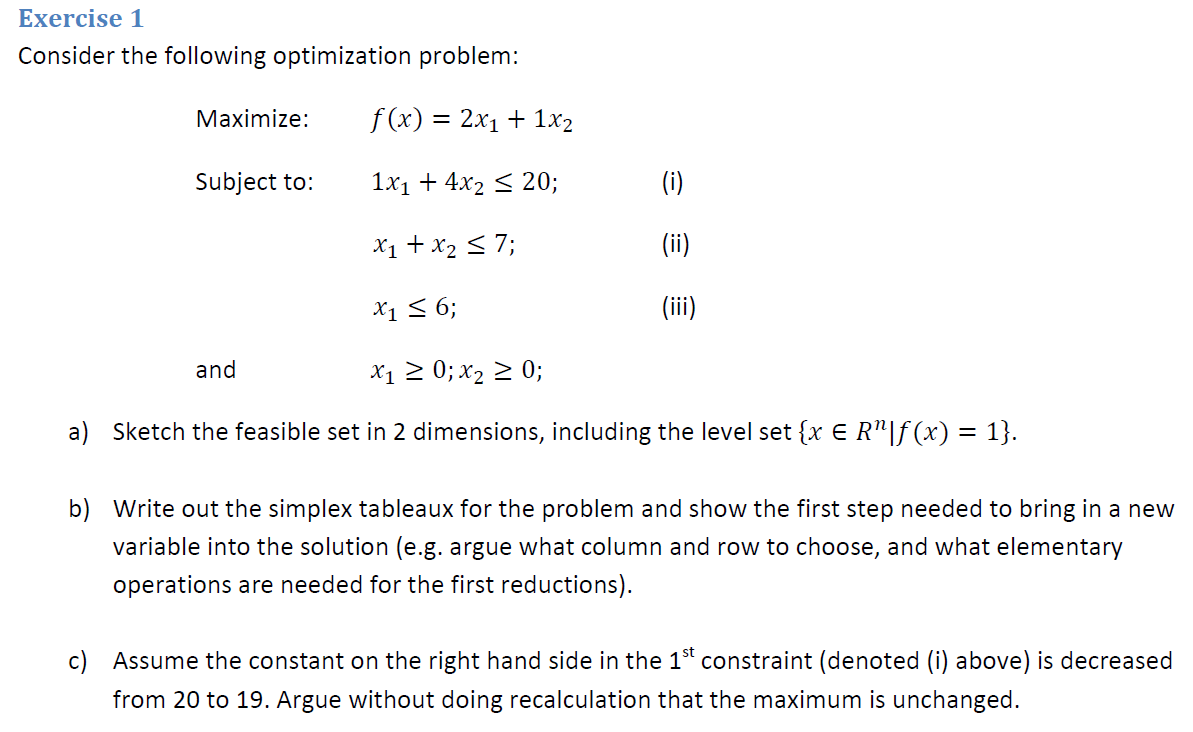

%a
%Feasible set:
% Define function and constraints
h1 = @(x1,x2) x1+4*x2-20

h1 = function_handle with value:
    @(x1,x2)x1+4*x2-20


h2 = @(x1,x2) x1+x2-7

h2 = function_handle with value:
    @(x1,x2)x1+x2-7


h3 = @(x1,x2) x1-6

h3 = function_handle with value:
    @(x1,x2)x1-6


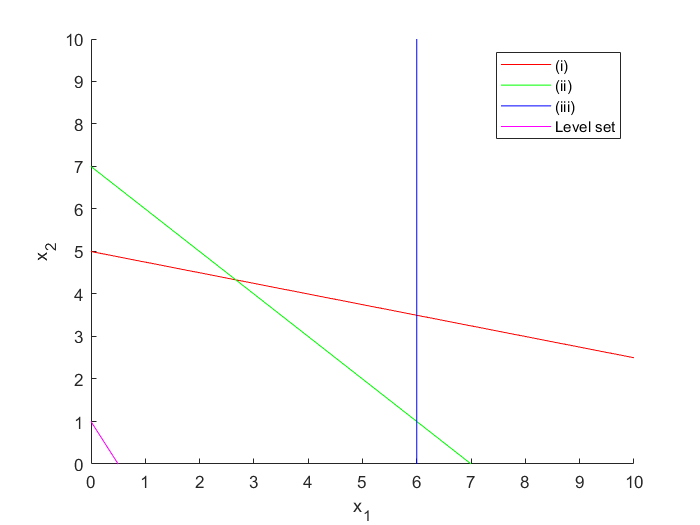

 
Initial tableau:
  Column 1

       1       
       1       
       1       
      -2       

  Column 2

       4       
       1       
       0       
      -1       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

       0       
       0       
       1       
       0       

  Column 6

       0       
       0       
       0       
       1       

  Column 7

      20       
       7       
       6       
       0       

Pivot point:
  Column 1

       3       

  Column 2

       1       

New tableau:
  Column 1

       0       
       0       
       1       
       0       

  Column 2

       4       
       1       
       0       
      -1       

  Column 3

       1       
       0       
       0       
       0       

  Column 4

       0       
       1       
       0       
       0       

  Column 5

      -1       
      -1       
      

ans =        6       
       1       
      10       
       0       
       0       
       0       



% Prepare plot
x1 = linspace(0,10);
x2 = linspace(0,10);
[X1,X2] = meshgrid(x1,x2);
figure
xlabel('x_1')
ylabel('x_2')
hold on


% (i)
contour(X1,X2,h1(X1,X2),[0,0],'r')
% (ii)
contour(X1,X2,h2(X1,X2),[0,0],'g')
% (iii)
contour(X1,X2,h3(X1,X2),[0,0],'b')

%level set:
f = @(x1,x2) 2*x1+x2;
level_sets = [1,1];
contour(X1,X2,f(X1,X2),level_sets,'m')

hold off
legend('(i)','(ii)','(iii)','Level set')

Initial table:

1   4   1   0   0   0   20

1   1   0   1   0   0   1

1   0   0   0   1   0   10

-----------------------------------

-2  -1  0   0   0   1   0

"-2" is most negatvie

calcualte which of the pivot is lowest

make that pivot point 1 and all others in same collumn 0

## c)

From the sketch it is apparent that the optimal solution at the intersection between constraint (ii) and (iii). The constraint imposed by (i) is far from the optimal point, and a decrease of 1 on the right hand side of inequality would not be enough to put the optimal solution outside the feasible set.

The right hand side of constraint (i) would have to be reduced to a value, which would case the intersection of (i) and (iii) to be below the intersection of (ii) and (iii) for the constraint to limit the found optimal solution.

## Exercise 2

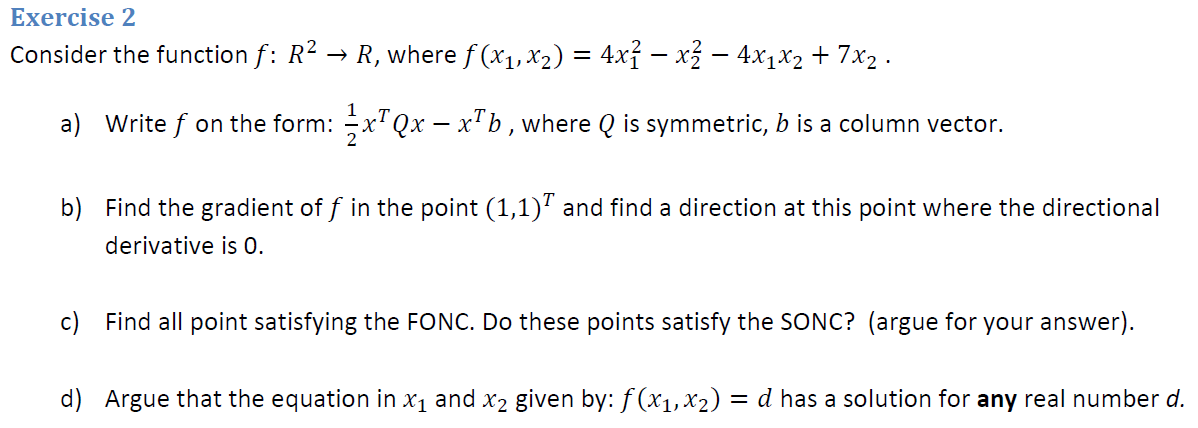

syms x1 x2 x
f = @(x1,x2) 4*x1^2 - x2^2 - 4*x1*x2 + 7*x2

f = function_handle with value:
    @(x1,x2)4*x1^2-x2^2-4*x1*x2+7*x2



%a 

Q = [ 4 -2;
     -2 -1];
 Q = Q*2

Q =        8             -4       
      -4             -2       


 b = [0;-7]; % always multiply b by -1
 
 fq = @(x) 1/2*x'*Q*x - x'*b

fq = function_handle with value:
    @(x)1/2*x'*Q*x-x'*b


 
%b
p = [1;1]

p =        1       
       1       



% First derivative (gradient)
syms x1 x2
df1_x1 = diff(fq([x1; x2]),x1);
df1_x2 = diff(fq([x1; x2]),x2);
Df = [df1_x1 df1_x2]

$$Df = \left(\begin{array}{cc} 4\,x_{1}-2\,x_{2}+4\,\bar{x_{1}}-2\,\bar{x_{2}} & 7-x_{2}-2\,\bar{x_{1}}-\bar{x_{2}}-2\,x_{1} \end{array}\right)$$

gradient = Df'

$$gradient = \left(\begin{array}{c} 4\,x_{1}-2\,x_{2}+4\,\bar{x_{1}}-2\,\bar{x_{2}}\\ 7-x_{2}-2\,\bar{x_{1}}-\bar{x_{2}}-2\,x_{1} \end{array}\right)$$


% The directional derivative in x0 can then be found
gradient_fnc = matlabFunction(gradient);
g11 = gradient_fnc(1,1)

g11 =        4       
       1       



%Derivative direction:
syms d1 d2
eqns = [[d1 d2]*g11==[0; 0], d1~=0, d2~=0];
sol = solve(eqns,d1,d2);
d = [sol.d1; sol.d2]

$$d = \left(\begin{array}{c} -\frac{1}{4}\\ 1 \end{array}\right)$$

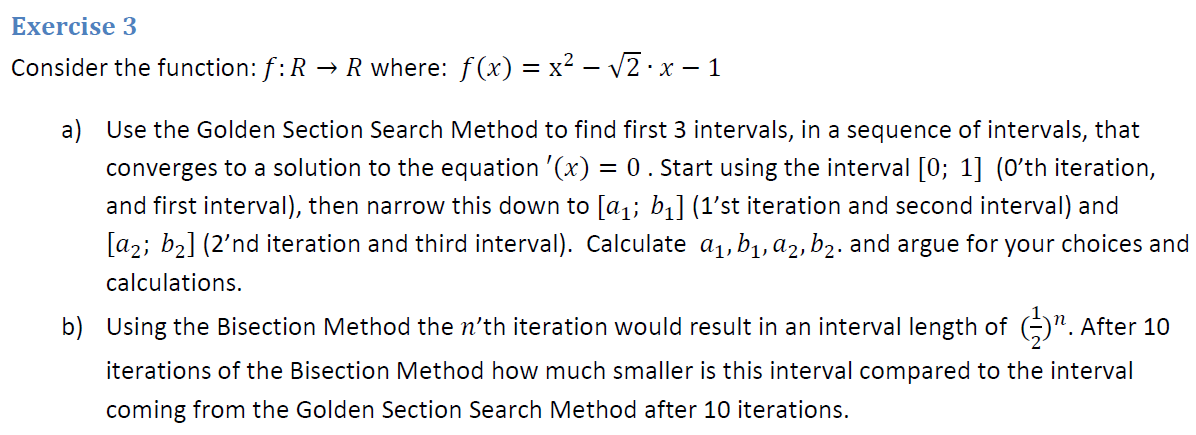

%a
syms x
f = @(x) x^2 - sqrt(2) * x - 1

f = function_handle with value:
    @(x)x^2-sqrt(2)*x-1


N = 2

N =        2       



% Initial interval definition
a_lim = 0;
b_lim = 1;

% Allocation of arrays
a = zeros(N,1)

a =        0       
       0       


b = zeros(N,1)

b =        0       
       0       


f_a = a;
f_b = b;
golden_search_summary = zeros(N,6)

golden_search_summary =        0              0              0              0              0              0       
       0              0              0              0              0              0       



% Golden search method iterations
rho = 0.382

rho =      191/500   


for i=1:N
    a(i) = a_lim+rho*(b_lim-a_lim);  
    b(i) = a_lim+(1-rho)*(b_lim-a_lim);
    
    f_a(i) = f(a(i));
    f_b(i) =  f(b(i));
    
    if f_a(i) < f_b(i)
       a_lim;
       b_lim = b(i);
    else
        a_lim = a(i);
        b_lim;
    end
    
    golden_search_summary(i,:) = [a(i) b(i) f_a(i) f_b(i) a_lim b_lim];
end
golden_search_summary

golden_search_summary =      191/500        309/500      -1616/1159     -6765/4534       191/500          1       
     212/343       1207/1580     -2353/1577     -3941/2633       212/343          1       


x_interval = [a_lim b_lim]

x_interval =      212/343          1       



%b

The interval length of the Golden Section method at iteration *n* is given by:


$${\left(1-\rho \text{ }\right)}^n$$


The interval length of Bisection method at iteration *n* is given by:


$${\left(\frac{1}{2}\right)}^n$$


Comparing the two methods:

Golden section: ${\left(1-\rho \text{ }\right)}^{10} =81\ast {10}^4$

Bisection: $0\ldotp 5^{10} =9,766\ast {10}^4$

This means that the interval of the Golden section is approximately $\frac{81\ast {10}^4 }{9\ldotp 766\ast {10}^4 }=8\ldotp 321$times larger than the bisection interval.

golden_section = (1-rho)^10

golden_section =       84/10337 


bisection = 0.5^10

bisection =        1/1024  


ratio = golden_section/bisection

ratio =     1140/137   


## Exercise 4

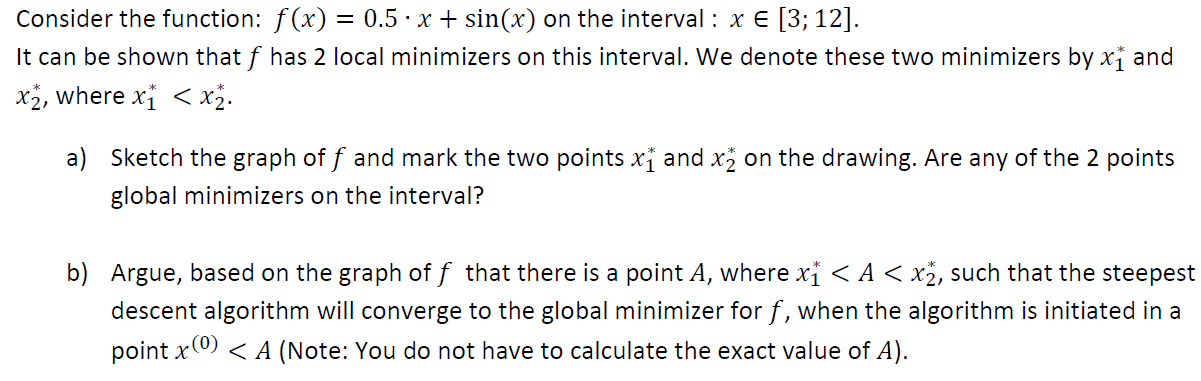

%a
syms x
f = @(x) 0.5 * x + sin(x)

f = function_handle with value:
    @(x)0.5*x+sin(x)


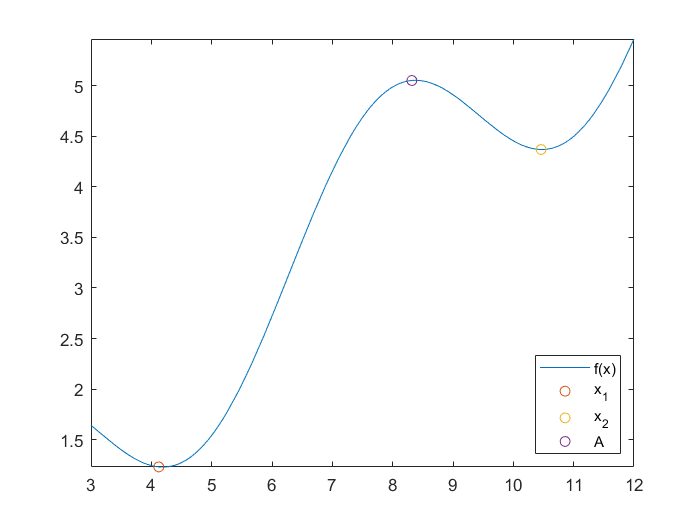


fplot(f, [3,12])
hold on
scatter(4.123,1.23)
scatter(10.46,4.37)
scatter(8.318,5.053)
legend('f(x)','x_1','x_2','A','location','southeast')
hold off


%b

## b)

The Steepest Descent algorithm is a gradient descent algorithm, which means it utilizes the gradient in a point to determine the optimal step size for acheiving maximum decrease of the objective function.

The graph shows that the objection function $f\left(x\right)$ has a global maximum within the interval in the approximate point $\left\lbrack \begin{array}{c}
8\ldotp 318\\
5\ldotp 053
\end{array}\right\rbrack$. The global minimizer in the interval, $x_1$is located to the left of the maximum. Any starting point to the left of this maximum should therefore ensure that the steepest descent algorithm converges towards $x_1$.Any starting point to right of the maximum would cause the steepest descent algorithm to converge towards $x_2$.

A should therefore be placed in the global maximum within the interval:


$$A=\left\lbrack \begin{array}{c}
8\ldotp 318\\
5\ldotp 053
\end{array}\right\rbrack$$


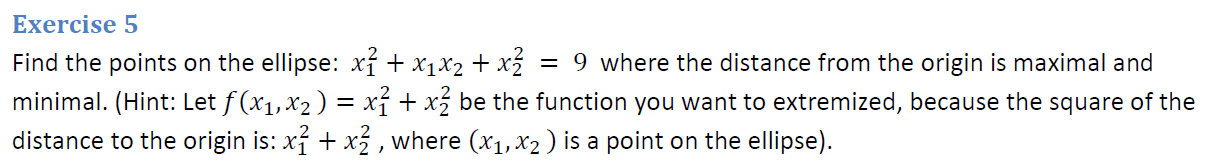

syms x1 x2
f = @(x1, x2) x1^2 + x1*x2 + x2^2

f = function_handle with value:
    @(x1,x2)x1^2+x1*x2+x2^2



zhandle = fcontour(f)

zhandle =   FunctionContour with properties:

     Function: @(x1,x2)x1^2+x1*x2+x2^2
    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 1/2
         Fill: 'off'
    LevelList: [10 20 30 40 50 60 70]

  Show all properties


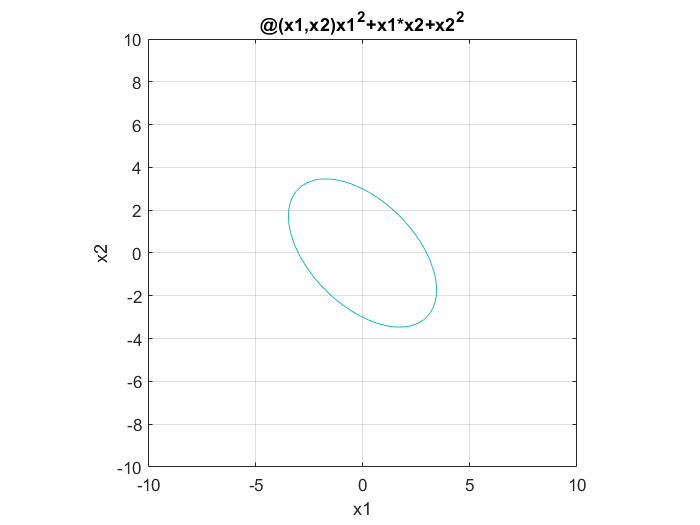


zhandle.LevelList = [9];
xlabel x1
ylabel x2
title(func2str(f))
grid on
zhandle.YRange = [-10,10];
zhandle.XRange = [-10,10];
axis equal

**maximize**: $f\left(x_1 ,x_2 \right)=x_1^2 +x_2^2$

**Subject** **to**: $h\left(x_1 ,x_2 \right)=x_1^2 +x_1 x_2 +x_2^2 -9=0$

syms x1 x2
x = [x1; x2];
f = @(x1,x2) x1^2+x2^2;
h = @(x1,x2)x1^2+x1*x2+x2^2-9;

syms lambda
l = f(x1,x2)+lambda*h

$$l = \lambda \,\left({x_{1}}^{2}+x_{1}\,x_{2}+{x_{2}}^{2}-9\right)+{x_{1}}^{2}+{x_{2}}^{2}$$


dlx1 = diff(l,x1)

$$dlx1 = 2\,x_{1}+\lambda \,\left(2\,x_{1}+x_{2}\right)$$

dlx2 = diff(l,x2)

$$dlx2 = 2\,x_{2}+\lambda \,\left(x_{1}+2\,x_{2}\right)$$

dll = diff(l,lambda)

$$dll = {x_{1}}^{2}+x_{1}\,x_{2}+{x_{2}}^{2}-9$$


syms x1 x2 lambda
[x1, x2, lambda] = solve(dlx1==0,dlx2==0,dll==0, x1, x2, lambda)

$$x1 = \left(\begin{array}{c} \sqrt{3}\\ 3\\ -3\\ -\sqrt{3} \end{array}\right)$$

$$x2 = \left(\begin{array}{c} \sqrt{3}\\ -3\\ 3\\ -\sqrt{3} \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{2}{3}\\ -2\\ -2\\ -\frac{2}{3} \end{array}\right)$$


x1 = [sqrt(3); sqrt(3)];
x2 = [3; -3];
x3 = [-3; 3];
x4 = [-sqrt(3); -sqrt(3)];



f = @(x1, x2) x1^2 + x1*x2 + x2^2;
zhandle = fcontour(f);

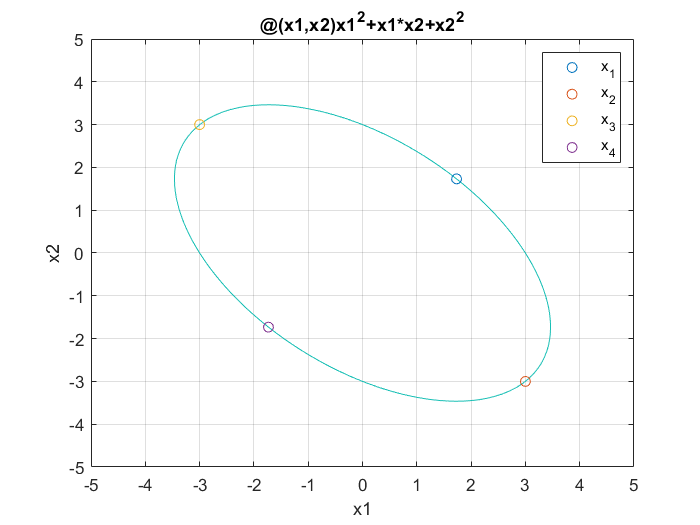

hold on
zhandle.LevelList = [9];
xlabel x1
ylabel x2
h1 = scatter(x1(1),x1(2));
h2 = scatter(x2(1),x2(2));
h3 = scatter(x3(1),x3(2));
h4 = scatter(x4(1),x4(2));
title(func2str(f));
grid on
legend([h1 h2 h3 h4],'x_1','x_2','x_3','x_4')
hold off